% MidRiseQuantization
clc;
clear;

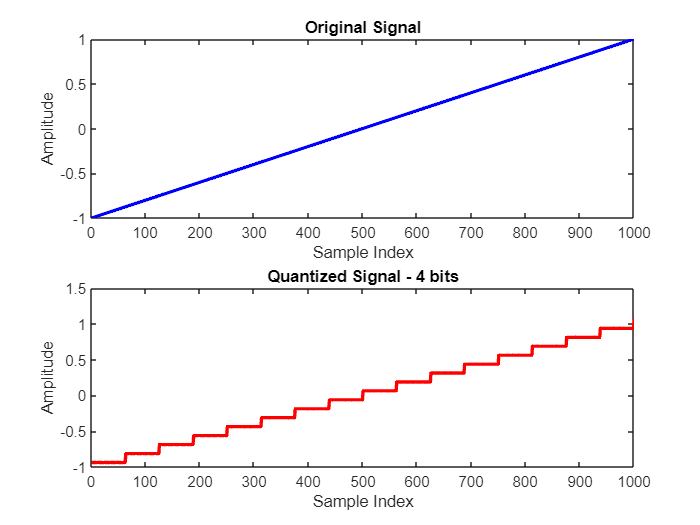

ip_sig=linspace(-1, 1, 1000);
num_bits = 4;
riseQuantizedOutput=midRiseQuantization(ip_sig,num_bits);

figure;
subplot(2,1,1);
plot(ip_sig,'b','LineWidth',2);
title('Original Signal');
xlabel('Sample Index');
ylabel('Amplitude');
hold on
subplot(2,1,2);
plot(riseQuantizedOutput,'r','LineWidth',2);
title(['Quantized Signal - ',num2str(num_bits),' bits']);
xlabel('Sample Index');
ylabel('Amplitude');

function QuantizedOutput=midRiseQuantization(ip_sig,num_bits)
    % Input signal should be in the range [-1,1]
    % numb_bits is the number of bits for quantization

    % Calculate the step size
    step_size=2/(2^(num_bits));

    % Quantize the input signal
    QuantizedOutput=floor(ip_sig/step_size)*step_size+step_size/2;
end